%{
cd /Users/joyce/Github/isetcam;
addpath(genpath(pwd));
cd /Users/joyce/Github/isetfluorescence;
addpath(genpath(pwd));
cd /Users/joyce/Github/oraleye/;
addpath(genpath(pwd));
cd /Users/joyce/Github/oe_tongue_lip/;
addpath(genpath(pwd));
%}

ieInit;
wave = 500:595;
normWave = 520;
% fise_plotDefaults;
 

## Read the saved model fluorophores

These have no blood.  The blood will be read in during the fitting process with oeSolveBlood.

fname = fullfile(oeTongueLipRootPath,'data','savedFluorophores');
[savedFluorophores,~,comment] = ieReadSpectra(fname,wave);
%{
plotRadiance(wave,savedFluorophores);
legend(comment.names);
%}

## Read the external data

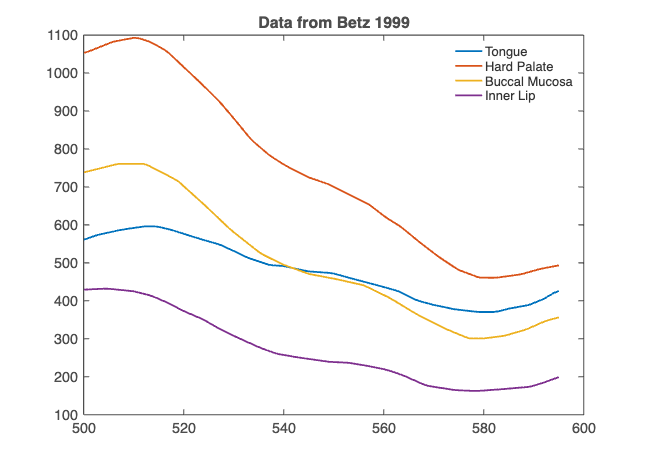


TongueBetz = ieReadSpectra('TongueBetz1999.mat',wave);
HardPalateBetz  = ieReadSpectra('HardPalateBetz1999.mat',wave); 
BuccalMucosaBetz  = ieReadSpectra('BuccalMucosaBetz1999.mat',wave);
InnerLipBetz = ieReadSpectra('InnerLipBetz1999.mat',wave);

ieFigure; 
plot(wave,TongueBetz); hold on;
plot(wave,HardPalateBetz);
plot(wave,BuccalMucosaBetz); 
plot(wave,InnerLipBetz);
title('Data from Betz 1999');
legend('Tongue','Hard Palate','Buccal Mucosa','Inner Lip'); 
lines = findall(gca, 'Type', 'Line');
set(lines, 'LineWidth', 2);
set(gca,'fontsize',16); set(gca, 'FontName', 'Helvetica');

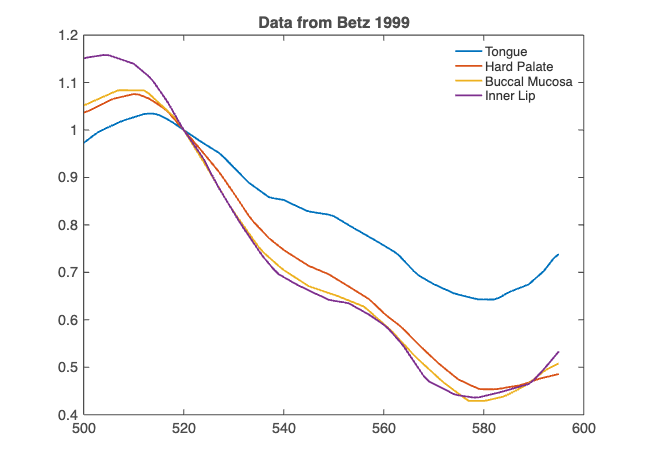




TongueBetz  = TongueBetz /TongueBetz(wave == 520);
HardPalateBetz  = HardPalateBetz /HardPalateBetz(wave == 520);
BuccalMucosaBetz  = BuccalMucosaBetz /BuccalMucosaBetz(wave == 520);
InnerLipBetz  = InnerLipBetz  /InnerLipBetz(wave == 520);

ieFigure; 
plot(wave,TongueBetz); hold on;
plot(wave,HardPalateBetz);
plot(wave,BuccalMucosaBetz); 
plot(wave,InnerLipBetz);
title('Data from Betz 1999');
legend('Tongue','Hard Palate','Buccal Mucosa','Inner Lip');
lines = findall(gca, 'Type', 'Line');
set(lines, 'LineWidth', 2);
set(gca,'fontsize',16); set(gca, 'FontName', 'Helvetica');

## Fit the model to tongue data

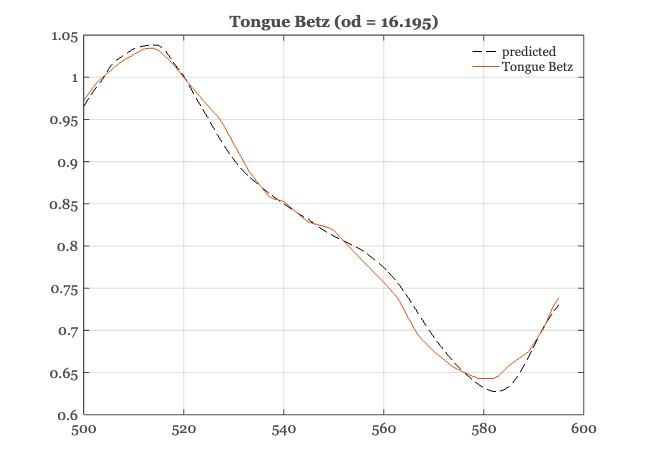

[odT,weightsT,finalFluorophoresT] = oeSolveBlood(wave,TongueBetz,savedFluorophores);
predictedT = finalFluorophoresT*weightsT(:);
ieFigure;
plot(wave,predictedT,'k--',wave,TongueBetz);
grid on;
title(sprintf('Tongue Betz (od = %.3f)',odT));
legend("predicted","Tongue Betz");


labels = {'Blood', 'Collagen-blood', 'FAD', 'Porphyrin', 'Chlorophyll-a', 'Keratin'};
values = [odT; weightsT(:)]; 
maxLabelWidth = max(cellfun(@length, labels));
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Tongue\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

Tissue: Tongue


         Blood  16.20
Collagen-blood  9.60
           FAD  0.42
     Porphyrin  0.00
 Chlorophyll-a  0.00
       Keratin  0.59


## Fit the model to the Hard Palate data

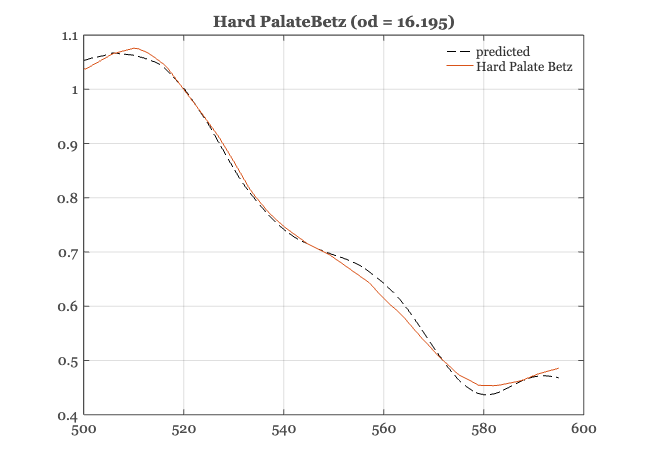

[odH,weightsH,finalFluorophoresH] = oeSolveBlood(wave,HardPalateBetz,savedFluorophores);
predictedH = finalFluorophoresH*weightsH(:);
ieFigure;
plot(wave,predictedH,'k--',wave,HardPalateBetz);
grid on;
title(sprintf('Hard PalateBetz (od = %.3f)',odT));
legend("predicted","Hard Palate Betz");

labels = {'Blood', 'Collagen-blood', 'FAD', 'Porphyrin', 'Chlorophyll-a', 'Keratin'};
values = [odH; weightsH(:)]; 
maxLabelWidth = max(cellfun(@length, labels));
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Hard Palate\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

Tissue: Hard Palate


         Blood  4.48
Collagen-blood  7.95
           FAD  0.53
     Porphyrin  0.00
 Chlorophyll-a  0.00
       Keratin  0.14


## Fit the model to the inner lip data

only use collagen and FAD - no keratin in inner lip

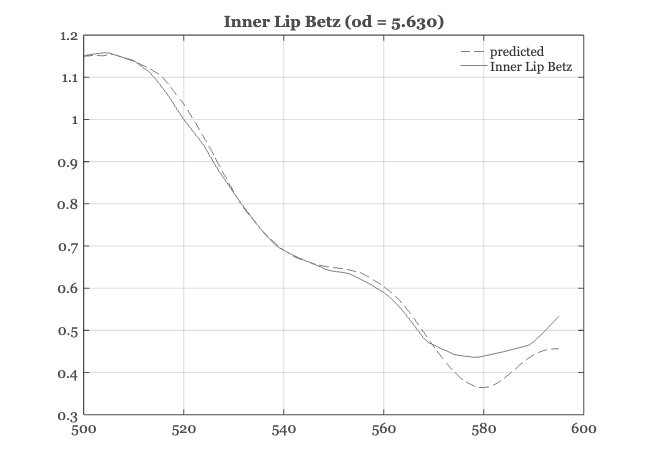

[odL,weightsL,finalFluorophoresL] = oeSolveBlood(wave,InnerLipBetz,savedFluorophores(:,1:2));
predictedL = finalFluorophoresL*weightsL(:);
ieFigure;
plot(wave,predictedL,'k--',wave,InnerLipBetz,'Color',[1 1 1]*0.5);
grid on;
legend({'predicted','Inner Lip Betz'});
title(sprintf('Inner Lip Betz (od = %.3f)',odL));

labels = {'Blood', 'Collagen-blood', 'FAD'};
values = [odL; weightsL(:)]; 
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Inner Lip\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

Tissue: Inner Lip


         Blood  5.63
Collagen-blood  11.32
           FAD  0.57


## Fit the model to the Buccal Mucosa data 

only use collagen and FAD - no keratin in inner lip

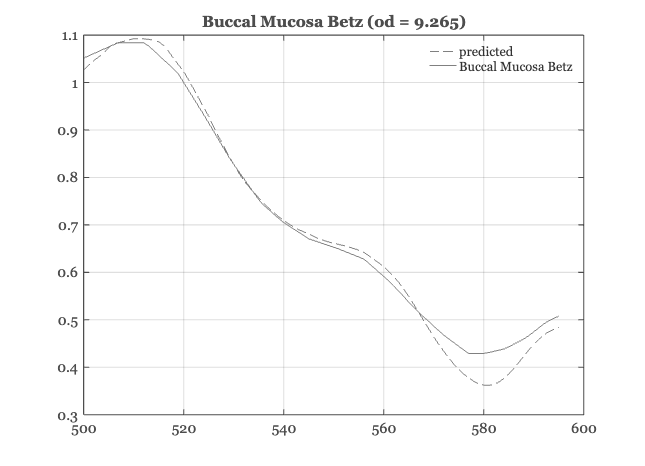

[odB,weightsB,finalFluorophoresB] = oeSolveBlood(wave,BuccalMucosaBetz,savedFluorophores(:,1:2));
predictedB = finalFluorophoresB*weightsB(:);
ieFigure;
plot(wave,predictedB,'k--',wave,BuccalMucosaBetz,'Color',[1 1 1]*0.5);
grid on;
legend({'predicted','Buccal Mucosa Betz'});
title(sprintf('Buccal Mucosa Betz (od = %.3f)',odB));


labels = {'Blood', 'Collagen-blood', 'FAD'};
values = [odB; weightsB(:)]; 
for i = 1:length(labels)
    if i==1, fprintf('Tissue: Oral Mucosa\n'); end
    fprintf('%*s  %.2f\n', maxLabelWidth, labels{i}, values(i));
end

Tissue: Oral Mucosa


         Blood  9.27
Collagen-blood  12.15
           FAD  0.69
